# **Instrumented Projectile Path**

### **The following Live Script is designed to interpret CSV data obtained from the Instrumental Projectile Project. Once you have the data handy, you can read it in this notebook and interpret the data.**

%Reads a csv file of recorded data
%Edit the path to display your raw data file, MATLAB accepts .csv and .txt data formats in addition to others.
ReadingsTable = readtable("InstrumentalProjectilePath/9Taps.txt")

ReadingsTable = 100×6 table
    Acceleration_x    Acceleration_y    Acceleration_z    Gyro_x    Gyro_y    Gyro_z
    ______________    ______________    ______________    ______    ______    ______

        -0.34             -1.11             12.93          0.17      0.18     -0.04 
         0.68             -0.74             10.71         -0.38     -0.45     -0.23 
         0.94              -0.9               9.1          0.18     -0.15      -0.1 
         1.19             -0.64              9.18         -0.08     -0.23      0.01 
         1.69             -0.63             10.46          0.18      0.09     -0.02 
         1.35             -0.82              10.1         -0.07      0.27       0.1 
         0.64             -0.43              9.06          0.02      0.47      0.08 
  

%Deduce the time period from each reading
%Because the data can be read with or without a time period taken, we first
%deduce if the time column exists in our table and act accordingly
tCol_Exist = strcmp('Timestamp',ReadingsTable.Properties.VariableNames);
t_Exist = tCol_Exist(tCol_Exist==1);
if(t_Exist)
    %If the time was taken,
    % It is measured in milliseconds and converted into seconds for
    % calculations over the time periods
t_Period = abs(ReadingsTable{2:height(ReadingsTable),1} - ReadingsTable{1:height(ReadingsTable)-1,1}) / 1000;
    % Contains the exact time recorded in seconds
t_Value = (ReadingsTable.Timestamp(1:end)/1000);
else
    % If time doesn't exist
    % Enter the estimated value of the time periods in milliseconds
t_Period = str2double("10")/1000;
    % Generates an estimated table of time values
val = height(ReadingsTable) * t_Period
t_Value = 0:t_Period:(val -  t_Period)
    % Generates an estimated table of time periods
t_Period = ones(height(ReadingsTable)-1,1) .* t_Period
end

val = 1

t_Value =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


t_Period =     0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100


%Calculates the total magnitude of the Acceleration, Including Gravity
mGAx = sqrt((ReadingsTable{:, "Acceleration_x"}).^2 ...
          + (ReadingsTable{:, "Acceleration_y"}).^2 ...
          + (ReadingsTable{:, "Acceleration_z"}).^2);
%Calculates the total magnitude of the Acceleration, not ingluding gravity.
%Gravity in the resting projectile was recorded to be resting at 10.4m/s^2.
mgAx = (mGAx - 10.4);
mgAx = mgAx(1:end);
Vel = abs(mgAx(2:end) - mgAx(1:end-1)) .* t_Period;

mgAx = mgAx(2:end) - mgAx(1:end-1);
%Vel(end+1) = 0;

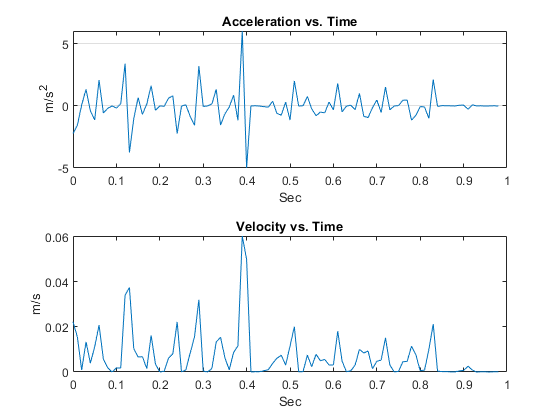

%Plotting the total acceleration vs time readings.
tiledlayout(2,1)

tile1 = nexttile;
plot(tile1, t_Value(1:end-1), mgAx)
title(tile1, 'Acceleration vs. Time')
xlabel(tile1,'Sec')
ylabel(tile1, 'm/s^2')

tile2 = nexttile;
plot(tile2, t_Value(1:end-1), Vel)  
title(tile2, 'Velocity vs. Time')
xlabel(tile2,'Sec')
ylabel(tile2, 'm/s')